# ASSIGNMENT 1

clear; close all; clc

## Data

### Turbine data:

N = 3;                    % [ ]      number of blades
V_ci = 4;                 % [m/s]    cut in wind speed
V_co = 25;                % [m/s]    cut out in wind speed
R_rotor = 178.3/2;        % [m]      rotor diameter 
A_rotor = pi * R_rotor^2; % [m^2]    rotor area
H = 119;                  % [m]      hub height
rho_air = 1.225;          % [kg/m^3] air density
V_rated = 11.4;           % [m/s]    rated wind speed
Jeq = 1.56e8;             % [kgm^2]  moment of inertia at the rotor
b = 2e5;                  % [Nms]    rotor damping

### Generator data:

I = 4800;                 % [kgm^2]  inertia
pp = 320;                 % [mH]     poles pairs
Lq = 1.8;                 % [mH]     q-axis inductance
Rs = 64;                  % [mOhm]   stator resistance
Fm = 19.49;               % [Wb]     magnets flux
f1 = 1;                   % [kHz]    Inverter switching frequency

### Wind data:

cd();


/Users/edoardomurgia/Università/Mechatronics Engineering/2° Anno/Primo Semestre/Renewable Energies/Homework 1



Wind_data = 'Wind_data.csv';   % Reed the .csv file filled with wind velocity data
data = readtable(Wind_data,'VariableNamingRule', 'preserve');
sampled_data = data.("Wind speed (m/s)");   % Extract column "Wind speed (m/s)"
clear Wind_data;

## Weibull fit

Probability density function that better fits the average wind speed over a year:


$$f(x; k, \lambda) = \frac{k}{\lambda} \left( \frac{x}{\lambda} \right)^{k-1} 
\exp\!\left[-\left(\frac{x}{\lambda}\right)^k \right], \quad x \geq 0$$


### Parameters:

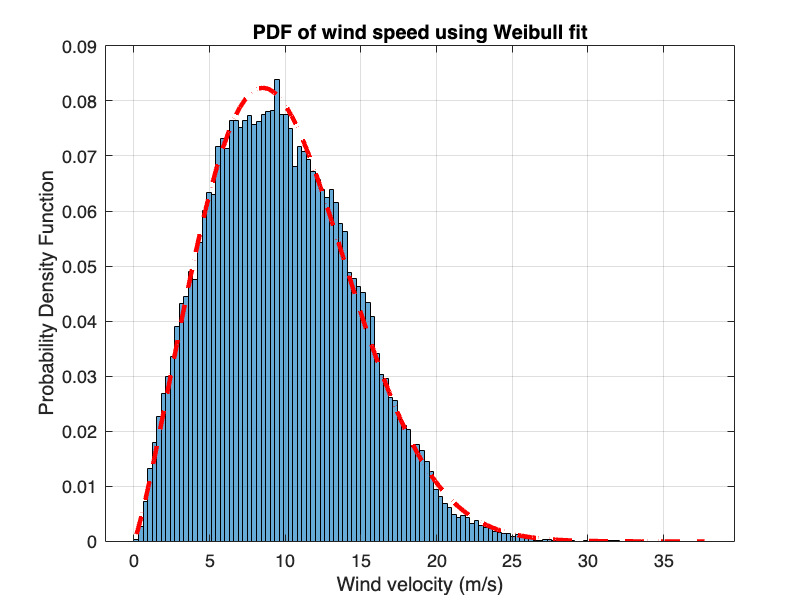

ans = 37.7100

% Find the parameters to use Weibull's fit through 'wblfit'
% Data is very dirty, so I keep only valid information
V_wind = sampled_data(sampled_data >= 0 & isnumeric(sampled_data));
clear sampled_data;

% 1. Weibull's distribution parameters extraction
phat = wblfit(V_wind);
k = phat(1);
lambda = phat(2);
clear phat

% 2. Wind speed values interval
V_w = linspace(min(V_wind), max(V_wind), 100);

% 3. Use the parameters to calculate the Weibull's fit
y_weibull = wblpdf(V_w, k , lambda);

% 4. Histogram and fitted lines
i = 1;
figure(i);
histogram(V_wind, 'Normalization', 'pdf');
hold on; % Working on the graph
plot(V_w, y_weibull, 'r--', 'LineWidth', 2.5); % Weibull's fit
xlabel('Wind velocity (m/s)');
ylabel('Probability Density Function');
title('PDF of wind speed using Weibull fit');
grid on;
hold off; % Closeing the graph

## Optimal Power Coefficient (Cp) and Tip Speed Rate (Lambda)

% BUILD AXIS
beta         = 0;                        % blades pitch angle = 0 [deg]
lambda_sweep = (2.0:0.1:12.8)';          % tip speed ratio axis from 2.0 to 15.0 []    

#### EXPONENTIAL FITTING FORMULA (empiric formula)

Power factor: $C_p(\lambda, \beta) = 0.55\left(\frac{116}{\kappa}-0.4\beta-5\right) e^{-\frac{21}{\kappa}}$

with:                $\frac{1}{\kappa} = \frac{1}{\lambda + 0.08\beta} - \frac{0.035}{1+\beta^3}$

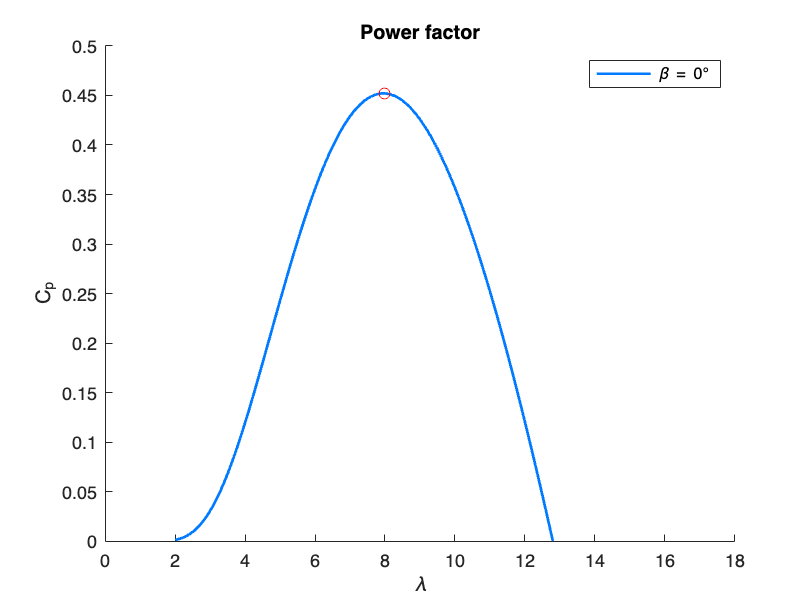

Cp_curve = PowerFactor(lambda_sweep, beta);
i = i + 1;
figure(i)
hold on
plot(lambda_sweep,Cp_curve,'-', 'Color','#007AFF', 'linewidth',1.5)
leg = ['\beta = ',num2str(beta),'°'];

% FIND PEAK POWER FACTOR VALUE lambda and pitch
Cp_opt = max(Cp_curve);         % Optimal Cp (the highest on the curve)
lambda_opt = lambda_sweep(find(~(Cp_curve - max(Cp_curve))));        %#ok<FNDSB> % Optimal tip speed ratio

plot(lambda_opt,Cp_opt,'or')        % Visualize the optimal point on the curve
hold off
ylim([0 0.5])
xlim([0 18])
title('Power factor')
xlabel(' \lambda ')
ylabel('C_p')
legend(leg)

# STALL REGULATED CONSTANT SPEED TURBINE

## Target and Nominal Omegas:

omega_rated = (lambda_opt * V_rated) / R_rotor; % Target angular velocity of the turbine based on the rated 
% velocity of wind

[maxValue, maxIndex] = max(y_weibull);
V_w = V_w';
V_nominal = V_w(maxIndex); % More frequent wind velocity
omega_nominal = (lambda_opt * V_nominal) / R_rotor; % Nominal angular velocity of the turbine based on the 
% nominal velocity of wind

## Lambda Plot


$$\lambda_{n} = \frac{\omega_{n} \cdot  R_{rotor}}{v_{wind}} $$


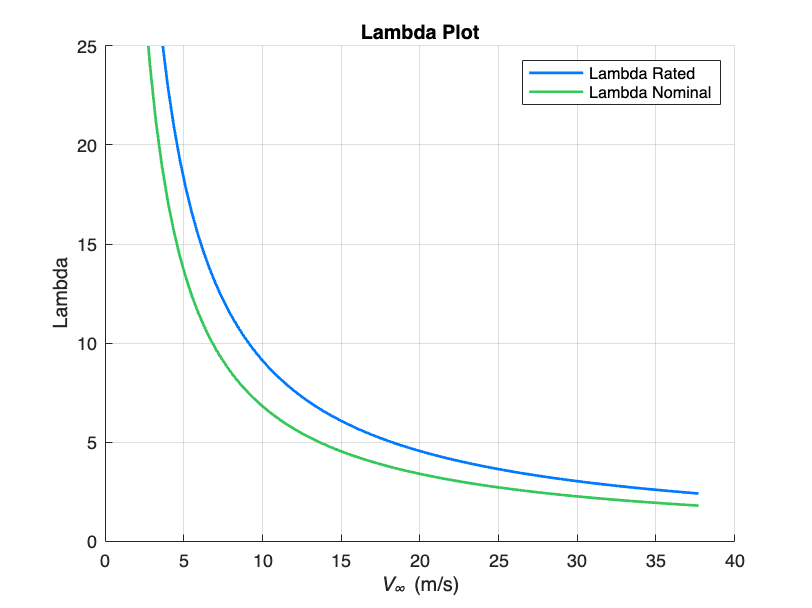

lambda_rated = omega_rated * R_rotor ./ V_w;
lambda_nominal = omega_nominal * R_rotor ./ V_w;
i = i + 1;
figure(i)
hold on
grid on
plot(V_w, lambda_rated, 'Color','#007AFF', 'linewidth',1.5);
plot(V_w, lambda_nominal, 'Color','#34C759','linewidth',1.5);
xlabel('\itV_\infty\rm (m/s)')
ylabel('Lambda')
title('Lambda Plot')
legend('Lambda Rated', 'Lambda Nominal', 'Location', 'northeast')
ylim([0 25])
hold off

## Power Profile:


$$P_{wind} = \frac{1}{2} \cdot \rho_{air} \cdot A_{rotor} \cdot v_{wind}^3$$



$$P_{extracted} = \frac{1}{2} \cdot \rho_{air} \cdot A_{rotor} \cdot v_{wind}^3 \cdot C_p\left(\lambda\right)$$


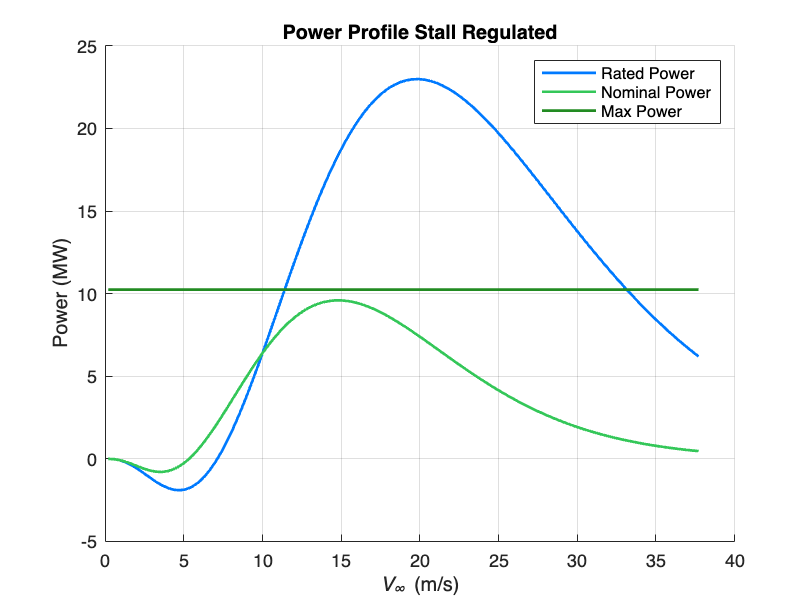

% Draw the power curve of the turbine. 
P_wind = 1/2 * rho_air * A_rotor * V_w.^3; % Power of the wind through the surface of the turbine

P_max = ones(size(V_w)) * 1/2 * rho_air * A_rotor * V_rated^3 * Cp_opt; % Max power produced by the turbine at rated velocity and optimal Cp
P_opt = P_wind * Cp_opt; % Theorical optimal power produced by the turbine

P_out_rated = P_wind .* PowerFactor(lambda_rated, 0); % Power produced by the turbine rotating at lambda rated (impossible)
P_out_nominal = P_wind .* PowerFactor(lambda_nominal, 0); % Power produced by the turbine rotating at lambda of most frequent speed

i = i + 1;
figure(i)
hold on
grid on
plot(V_w,P_out_rated / 1e6,'Color','#007AFF','linewidth',1.5)
plot(V_w,P_out_nominal / 1e6,'Color','#34C759','linewidth',1.5)
plot(V_w,P_max / 1e6,'Color','#228B22','lineWidth',1.5)
xlabel('\itV_\infty\rm (m/s)')
ylabel('Power (MW)')
title('Power Profile Stall Regulated')
legend('Rated Power', 'Nominal Power', 'Max Power', 'Location', 'northeast')
hold off

## Annual average Energy production:

### Omega = omega rated (not phisically possible)

annual_E_rated = TotalEnergy(V_wind, rho_air, A_rotor, lambda_sweep, Cp_curve, R_rotor, omega_rated) /2e9 % [GWh]

annual_E_rated = 12.7639

### Omega = omega nominal

annual_E_nominal = TotalEnergy(V_wind, rho_air, A_rotor, lambda_sweep, Cp_curve, R_rotor, omega_nominal) /2e9 % [GWh]

annual_E_nominal = 42.8817

### Omega = omega fixed = 0.77 [rad / s]

Need to **find** a constant rotation **velocity** that produces a **maximum power** of 10 MW (the nominal power of the turbine)

omega_fixed = 0.775; % I try several velocities of rotation till I reach a maximum power just below the 10 MW
lambda_fixed = omega_fixed * R_rotor ./ V_w;
P_out_fixed = P_wind .* PowerFactor(lambda_fixed, 0); % Real power produced by the turbine with omega = omega_fixed
max(P_out_fixed) % Maximum power produced by imposing omega_fixed as rotating velocity of the turbine

ans = 9.9949e+06

annual_E_fixed = TotalEnergy(V_wind, rho_air, A_rotor, lambda_sweep, Cp_curve, R_rotor, omega_fixed) /2e9 % [GWh]

annual_E_fixed = 44.0258

## Plots of the different Powers

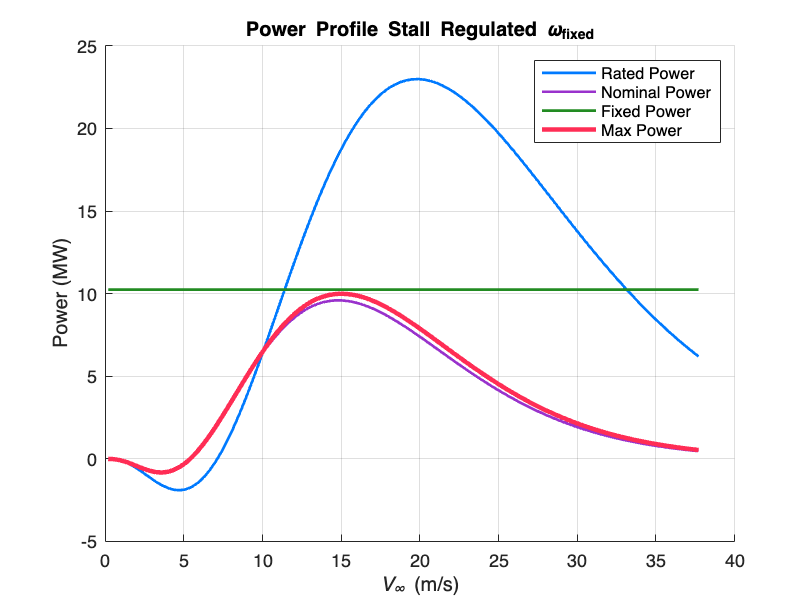

i = i + 1;
figure(i)
hold on
grid on
plot(V_w,P_out_rated / 1e6,'Color','#007AFF','linewidth',1.5)
plot(V_w,P_out_nominal / 1e6,'Color','#9932CC','linewidth',1.5)
plot(V_w,P_max / 1e6,'Color','#228B22','lineWidth',1.5)
plot(V_w,P_out_fixed / 1e6,'Color','#FF2D55','linewidth',2.5)
xlabel('\itV_\infty\rm (m/s)')
ylabel('Power (MW)')
title('Power Profile Stall Regulated \omega_{fixed}')
legend('Rated Power', 'Nominal Power', 'Fixed Power', 'Max Power', ...
       'Location', 'northeast')
hold off

## Wind - Power Production

In real-life applications, if the power were be negative the turbine would be powered off. Same thing happens when the wind speed overcomes the cut-off velocity. 

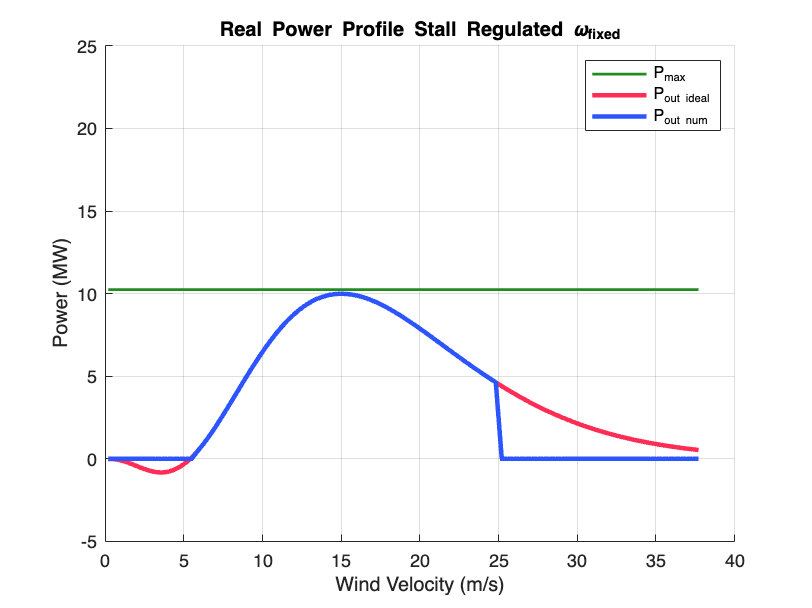

P_out_num_stall = P_out_fixed;
P_out_num_stall(V_w < 5.5 | V_w > V_co) = 0;
i = i + 1;
figure(i);
hold on
grid on
plot(V_w,P_max / 1e6,'Color','#228B22','lineWidth',1.5)
plot(V_w,P_out_fixed / 1e6,'Color','#FF2D55','linewidth',2.5)
plot(V_w,P_out_num_stall / 1e6, 'Color','#2D55FF', 'LineWidth', 2.5)
xlabel('Wind Velocity (m/s)');
ylabel('Power (MW)');
title('Real Power Profile Stall Regulated \omega_{fixed}')
ylim([-5 25])
legend('P_{max}', 'P_{out ideal}', 'P_{out num}');
hold off

# PITCH REGULATED VARIABLE SPEED TURBINE

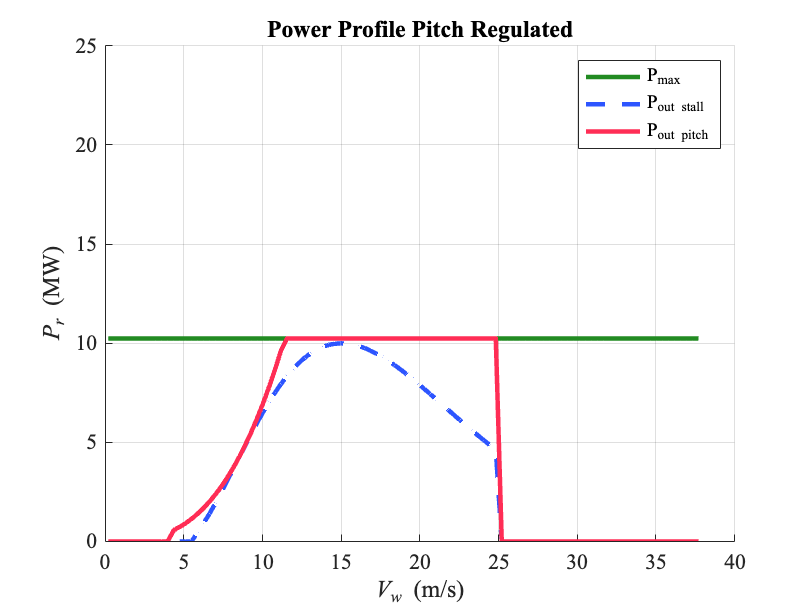

Prated = 1/2 * rho_air * A_rotor * V_rated^3 * Cp_opt;

% Working Regions 
I1 = find(V_w<V_ci);
I2 = find(V_w>=V_ci & V_w<=V_rated);
I3 = find(V_w>V_rated & V_w<=V_co);
I4 = find(V_w>V_co);

P_out_num_pitch(I1) = 0*V_w(I1);
P_out_num_pitch(I2) = 0.5*rho_air*V_w(I2).^3*A_rotor*Cp_opt;
P_out_num_pitch(I3) = Prated; 
P_out_num_pitch(I4) = 0*V_w(I4);

i = i + 1;
figure(i);
hold on
grid on
plot(V_w,P_max / 1e6,'Color','#228B22','lineWidth',2.5)
plot(V_w, P_out_num_stall / 1e6, 'Color', '#2D55FF', 'LineWidth', 2.5, 'LineStyle', '--')
plot(V_w,P_out_num_pitch/1e6,'Color','#FF2D55','linewidth',2.5)
ylim([0 25])
xlabel('\itV_w\rm (m/s)')
ylabel('\itP_r\rm (MW)')
title('Power Profile Pitch Regulated')
legend('P_{max}', 'P_{out stall}', 'P_{out pitch}');
set(gca,'FontSize',12,'fontname','times new roman')

## Annual Energy produced by the Pitch regulated turbine [GWh/anno]

% Total energy initialization 
E_pitch = 0;
% Duration of each measurement interval
int_h = 1/6;
for i = 1:length(V_wind)
    if (V_wind(i) >= V_ci & V_wind(i) <= V_rated)
        P = 1/2 * rho_air * V_wind(i)^3 * A_rotor * Cp_opt;
    elseif (V_wind(i) >= V_rated & V_wind(i) <= V_co)
        P = 1/2 * rho_air * V_rated^3 * A_rotor * Cp_opt;
    else
        P = 0;
    end
    E_pitch = E_pitch + P * int_h;
end
E_pitch / 2e9 %[GWh/anno]

ans = 49.6322

# JOULE AND VISCOUS LOSSES

## Joule:

**Power balance: **$u_d \cdot i_d + u_q \cdot i_q + R \cdot \left( i_d^2 + i_q^2 \right) + L \cdot \left( i_d \cdot \frac{di_d}{dt} + i_q \cdot \frac{di_q}{dt} \right) = \omega_{\text{me}} \cdot \Lambda_{mg} \cdot i_q = P_{out}$

**d-channel current** **= 0 **to maximize **torque** and since we are at **steady state** the **derivatives** of currents are **null.**

**q-channel current** can be found through:

$T_m^m \omega_m = \frac{3}{2}\omega_{me}\Lambda_{mg} i_q = P_{out}$,    that with    $\omega_{me} = p_p\omega_m$    allows to extract:

$i_q = \frac{2}{3} \cdot \frac{P_{out}}{p_p \cdot \omega_{m} \cdot \Lambda_{mg}$   ($\Lambda_{mg} = Fm$ in the following script).

iq = ones(1,length(V_w)); % Array of 100 values setted to 0

for j = 1:length(V_w)
    if(V_w(j) < V_ci)
        iq(j) = 0;
    elseif(V_w(j) >= V_ci && V_w(j) < V_rated)
        iq(j) = 2/3 * 0.5 * rho_air * V_w(j)^3 * A_rotor * Cp_opt / ((pp * ((lambda_opt * V_w(j)) / R_rotor) * Fm)); % [A]
    elseif(V_w(j) >= V_rated && V_w(j) <= V_co)
        iq(j) = 2/3 * Prated / (pp * omega_rated * Fm); % [A]
    elseif(V_w(j) > V_co)
        iq(j) = 0;
    end
end
iqmax = 2/3 * Prated / (pp * omega_rated * Fm) * ones(1,length(V_w));

% i = i + 1;
% figure(i);
% hold on
% grid on
% plot(V_w,iqmax / 1e3,'Color','#228B22','lineWidth',2.5) % Max iq [kA]
% plot(V_w,iq / 1e3,'Color','#FF2D55','lineWidth',2.5) % Actual iq [kA]
% xlabel('\itV_w\rm (m/s)','FontSize',12,'fontname','times new roman')
% ylabel('\iti_q\rm (kA)','FontSize',12,'fontname','times new roman')
% yticks(0:0.1:1.4);
% hold off

Dissipated Power through Joule effect:


$$P_{diss} = i_q^2 \cdot R_s$$


#### Joule effect Power Loss with respect to the wind velocity curve

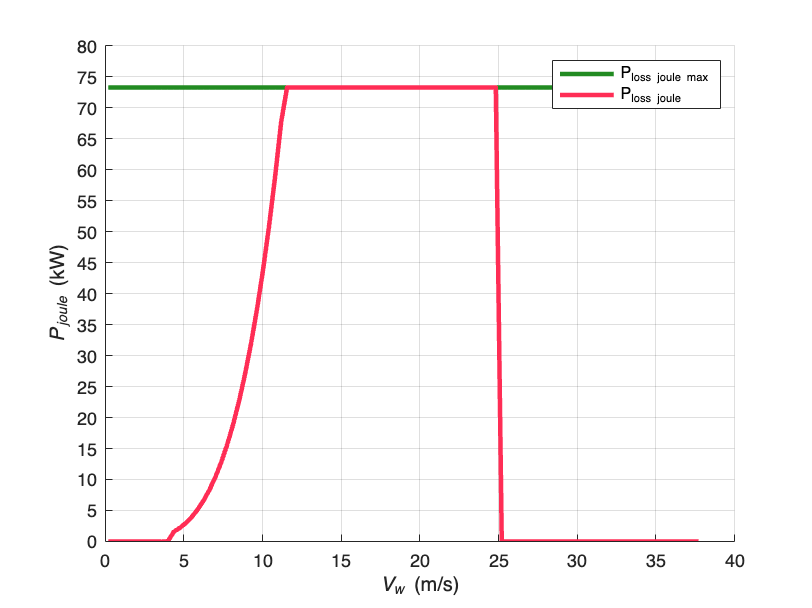

P_joule = iq.^2 * Rs * 1e-3; % [kW]

P_joule_max = iqmax.^2 .* Rs * 1e-3;

i = i + 1;
figure(i);
hold on
grid on
plot(V_w,P_joule_max / 1e3,'Color','#228B22','lineWidth',2.5) % Max Power loss (Joule) [kW]
plot(V_w,P_joule / 1e3,'Color','#FF2D55','lineWidth',2.5) % Actual Power loss (Joule) [kW]
xlabel('\itV_w\rm (m/s)')
ylabel('\itP_{joule}\rm (kW)')
legend('P_{loss joule max}', 'P_{loss joule}');
yticks(0:5:80);
hold off

## Viscous:


$$J_m \cdot \dot{\omega_m} + B_m \cdot \omega_m = T_w^m - T_m^m$$


Considering *steady state* conditions the angular velocity is constant in each interval of misiuration, so we can neglect the term related to it. We can calculate the viscous losses through:


$$P_{viscous} = B_m \cdot \omega_m$$


#### Viscous Power Loss with respect to the wind velocity curve

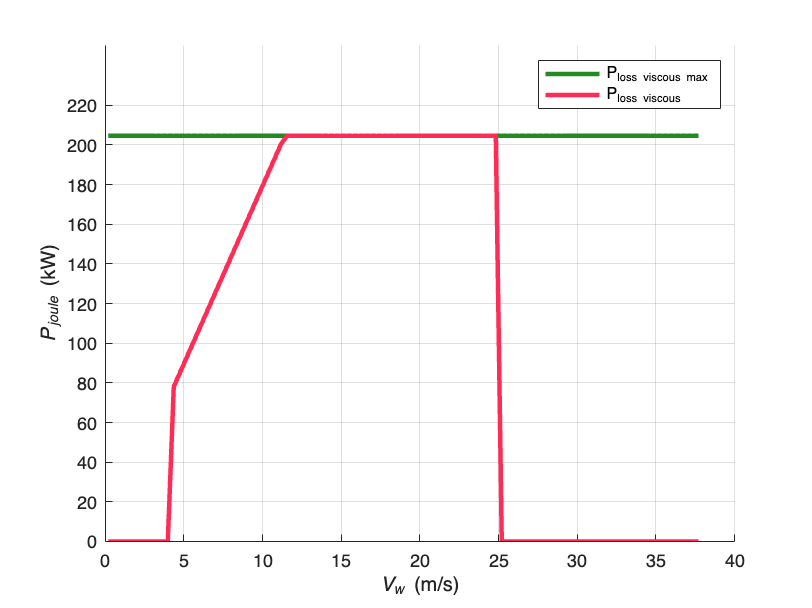


P_viscous = ones(1,length(V_w)); % Array of 100 values setted to 0

for j = 1:length(V_w)
    if(V_w(j) < V_ci)
        P_viscous(j) = 0;
    elseif(V_w(j) >= V_ci && V_w(j) < V_rated)
        P_viscous(j) = b * (lambda_opt * V_w(j)) / R_rotor;
    elseif(V_w(j) >= V_rated && V_w(j) <= V_co)
        P_viscous(j) = b * omega_rated;
    elseif(V_w(j) > V_co)
        P_viscous(j) = 0;
    end
end
P_viscous_max = ones(1, length(P_joule_max)) .* b * omega_rated;
i = i + 1;
figure(i);
hold on
grid on
plot(V_w,P_viscous_max / 1e3,'Color','#228B22','lineWidth',2.5) % Max Power loss (Viscous dumping) [kW]
plot(V_w,P_viscous / 1e3,'Color','#FF2D55','lineWidth',2.5) % Actual Power loss (Viscous dumping) [kW]
xlabel('\itV_w\rm (m/s)')
ylabel('\itP_{joule}\rm (kW)')
legend('P_{loss viscous max}', 'P_{loss viscous}');

yticks(0:20:230);
hold off

## Total Power Loss: Joule effect + viscous dumping

#### Total Power Loss with respect to the wind velocity curve

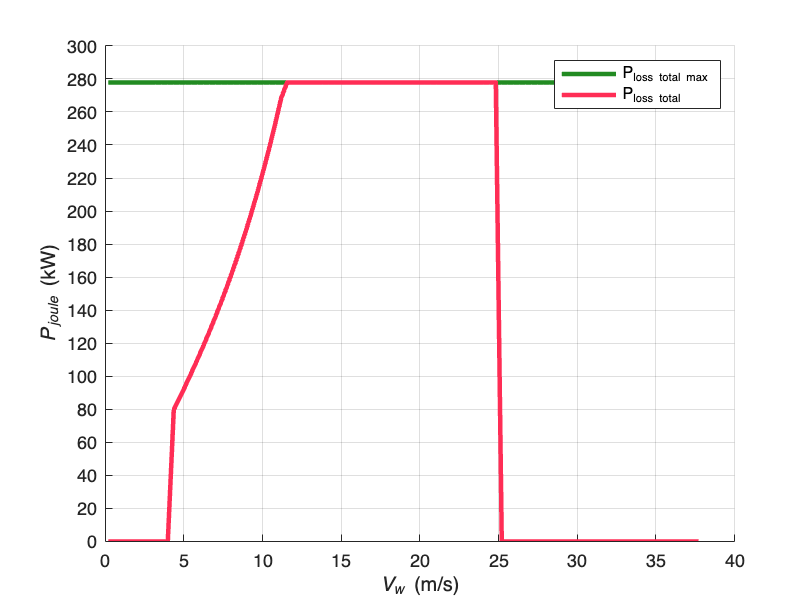

P_total_loss = P_joule + P_viscous;
P_total_loss_max = P_joule_max + P_viscous_max;
i = i + 1;
figure(i);
hold on
grid on
plot(V_w,P_total_loss_max / 1e3,'Color','#228B22','lineWidth',2.5) % Max Power loss (Joule + Viscous dumping) [kW]
plot(V_w,P_total_loss / 1e3,'Color','#FF2D55','lineWidth',2.5) % Actual Power loss (Joule + Viscous dumping) [kW]
xlabel('\itV_w\rm (m/s)')
ylabel('\itP_{joule}\rm (kW)')
legend('P_{loss total max}', 'P_{loss total}');
yticks(0:20:300);
hold off

#### Average Power Loss throughout the year due to both Joule and Viscous dumping effects

P_tl = 0;

for j = 1:length(V_wind)
    if(V_wind(j) >= V_ci && V_wind(j) < V_rated)
        P_tl = P_tl + b * (lambda_opt * V_wind(j)) / R_rotor + (2/3 * 0.5 * rho_air * V_wind(j)^3 * A_rotor * Cp_opt / ((pp * ((lambda_opt * V_wind(j)) / R_rotor) * Fm)))^2 * Rs * 1e-3 ;
    elseif(V_wind(j) >= V_rated && V_wind(j) <= V_co)
        P_tl = P_tl + b * omega_rated + (2/3 * Prated / (pp * omega_rated * Fm))^2 * Rs * 1e-3;
    end
end
AvTP_tl = P_tl/length(V_wind) % [W]

AvTP_tl = 1.8757e+05

#### Average Power Produced throughout the year

P_t = 0;
for i = 1:length(V_wind)
    if (V_wind(i) >= V_ci && V_wind(i) <= V_rated)
        P_t = P_t + 1/2 * rho_air * V_wind(i)^3 * A_rotor * Cp_opt;
    elseif (V_wind(i) >= V_rated && V_wind(i) <= V_co)
        P_t = P_t + 1/2 * rho_air * V_rated^3 * A_rotor * Cp_opt;
    end
end
AvTP = P_t/length(V_wind) % [W]

AvTP = 5.8291e+06

#### Average Efficency of the turbine throughout the year


$$\overline{\eta} = \frac{\overline{P}_{produced} - \overline{P}_{tot-loss}}{\overline{P}_{produced}}$$


eta = (AvTP - AvTP_tl)/AvTP

eta = 0.9678